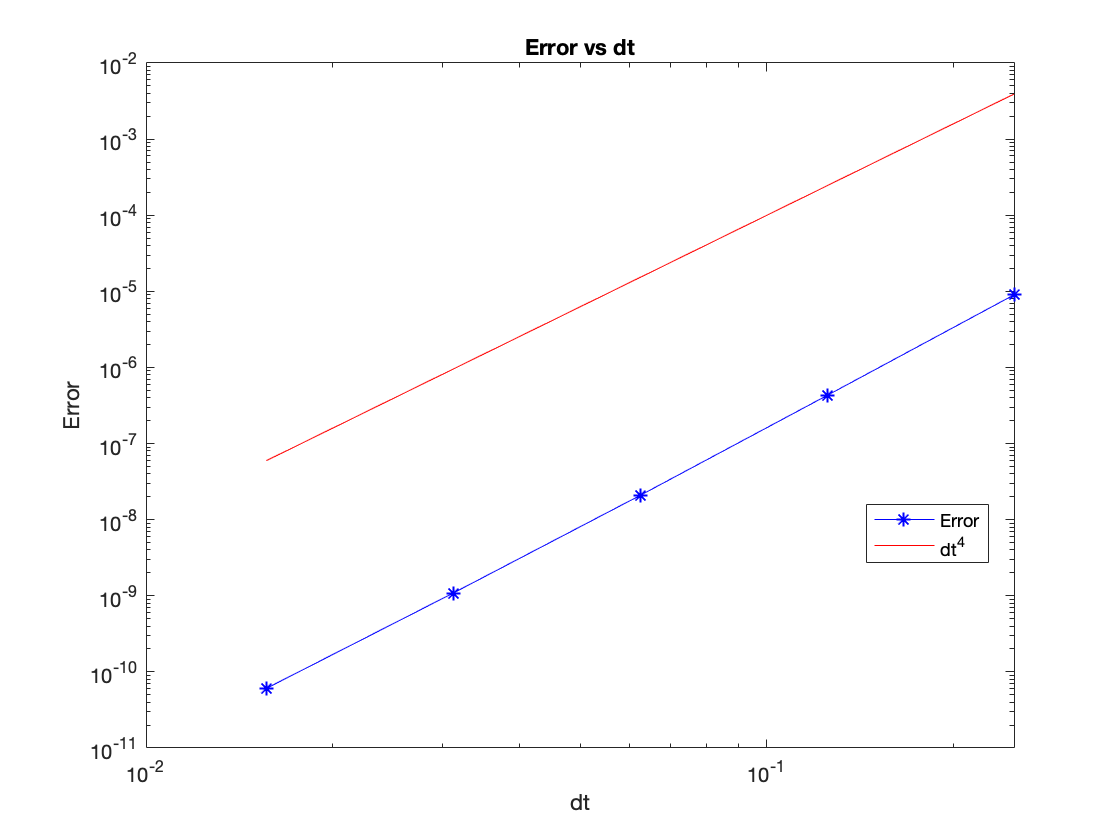

% Problem 3
% Use Classical R-K 4 to solve the ODE
T = 0.5;
n = 2.^[1:5]; % different step size
DT = T./n; % step sizes
f = @(u,t) (1-2*t)*u;
u_exact = @(t) exp(1/4-(1/2-t).^2);
error = zeros(1,5);
for i = 1:5
    dt = DT(i);
    x = 0:dt:T;
    u = zeros(1,length(x));
    u(1)=1;
    for j = 1:(length(x)-1)
        tn = x(j);
        Y1 = u(j);
        Y2 = Y1 + dt/2*f(Y1,tn);
        Y3 = Y1 + dt/2*f(Y2,tn+dt/2);
        Y4 = Y1 + dt*f(Y3,tn+dt/2);
        u(j+1) = u(j) + dt/6*(f(Y1,tn)+2*f(Y2,tn+dt/2)+2*f(Y3,tn+dt/2)+...
            f(Y4,tn+dt));
    end
    error(i) = abs(u_exact(T)-u(end));
end
loglog(DT, error,"b-*");
hold on;
loglog(DT,DT.^4, "r-");
% We can see it's 4th order of accuracy since the slope is the same as 
% the loglog plot for error
legend("Error","dt^4","Location","best");
title("Error vs dt")
xlabel("dt")
ylabel("Error")